# Hunt for a sensible LQI solution - part 1

Load the Linearised quadcopter+pendulum model

load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Control design:

We'll use the approach described by the LQI() function, ie::

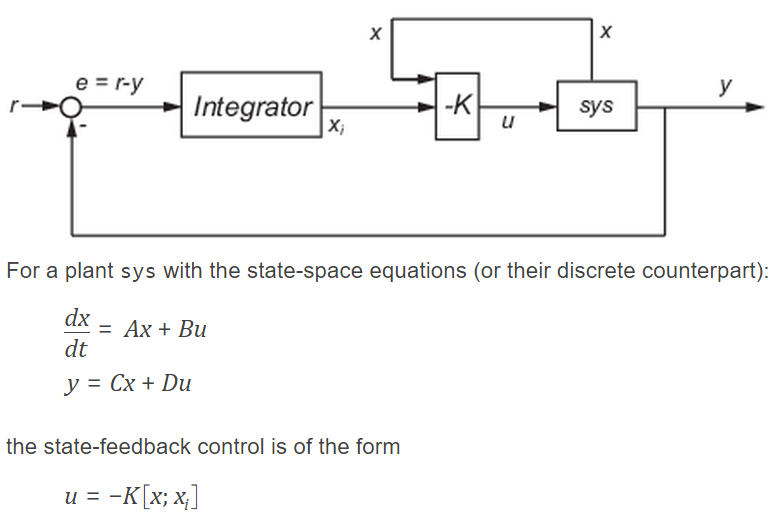

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;

Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

%tmp_N  = 1e4;

res_T.tf_is_good   = false;
res_T.K            = [];
res_T.p            = [];
res_T.tf_all_p_neg = false;
res_T.p_first      = 0;
res_T.K_av         = 0;
res_T.g_Q          = 0;
res_T.g_R          = 0;


% tmp_N       = 7e5;
% gg_list     = 1:tmp_N;
gg_list = 1:1e5;
%gg_list = 2e4:6e4;
res_array   = repmat(res_T, [1,length(gg_list)]);

for gg=1:length(gg_list)

    %fprintf('\n .. got one !')
    if(0==mod(gg,1000))
        fprintf("\n ... completed <%d> trials", gg);
    end

   try
       gg_VALUE   = gg_list(gg);
       [K, p_lqi, Q, R] = LOC_do_LQI(my_LIN_PLANT, 1, gg_VALUE, Nx, Ny, Nu);
       res_array(gg).tf_is_good = true;
       res_array(gg).K = K;
       res_array(gg).p = p_lqi;
       if( all( real(p_lqi) < 0 ))
           res_array(gg).tf_all_p_neg = true;           
       end
       res_array(gg).p_first = p_lqi(1);
       
       res_array(gg).K_av = mean(abs(K), 'all');
       res_array(gg).g_Q  = 1;
       res_array(gg).g_R  = gg_VALUE; 
       res_array(gg).g_R_mat  = R; 
       res_array(gg).g_Q_mat  = Q;        
   catch
       
   end
   
end % for


 ... completed <1000> trials
 ... completed <2000> trials
 ... completed <3000> trials
 ... completed <4000> trials
 ... completed <5000> trials
 ... completed <6000> trials
 ... completed <7000> trials
 ... completed <8000> trials
 ... completed <9000> trials
 ... completed <10000> trials
 ... completed <11000> trials
 ... completed <12000> trials
 ... completed <13000> trials
 ... completed <14000> trials
 ... completed <15000> trials
 ... completed <16000> trials
 ... completed <17000> trials
 ... completed <18000> trials
 ... completed <19000> trials
 ... completed <20000> trials
 ... completed <21000> trials
 ... completed <22000> trials
 ... completed <23000> trials
 ... completed <24000> trials
 ... completed <25000> trials
 ... completed <26000> trials
 ... completed <27000> trials
 ... completed <28000> trials
 ... completed <29000> trials
 ... completed <30000> trials
 ... completed <31000> trials
 ... completed <32000> trials
 ... completed <33000> trials
 ... completed <34


nnz([res_array.tf_is_good])

ans = 4928

Save the results to a MAT file

save('bh_results_HUNT_part_1.mat', 'res_array')

And we're done

fprintf('\n ... we are finished here ! \n')


 ... we are finished here ! 


# Local Subfunctions only beyond this point

function [K, p_lqi, Q, R] = LOC_do_LQI(my_LIN_PLANT, g_Q, g_R, Nx, Ny, Nu)

    tmp = g_Q*[ones(1, Nx+Ny)];
    
    tmp(19:21) = [2,2,1500];
    %tmp(19:21) = [1000,1000,1000];
    %tmp(1:3) = [1000,1000,1000];
    %tmp(19:21) = [2,2,1500];
    Q   = diag(tmp); 
    tmp = g_R*[1,1,1,1];
    R = diag(tmp); 
    
    [K,~,~] = lqi(my_LIN_PLANT,Q,R,[]);

    
    A = my_LIN_PLANT.A;
    B = my_LIN_PLANT.B;
    C = my_LIN_PLANT.C;
    
    A_hat = [  A,   zeros(Nx,Ny);
              -C,   zeros(Ny,Ny) ];
      
    B_hat = [ B;
              zeros(Ny,Nu) ];
          
    p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) );
    
end